#### Name/Last Name: Chawakorn Chaichanawirote

#### Student ID : 59340500013

# FRA333 : Intro to Robotics

## Assignment 10: Trajectory Generation

### Problem 2: Implementing trajcetory

For this exercise, we will use 3 dimensional matrix to store the coefficients.

The first dimension represents each joint of the robot. For this homework, there is only one degree of freedom. Therefore, there is only 1 row.

The second dimension represents the term in the polynomial from the zeroth-order to the n-th order. For this homework, the trajectory is cubic. Therefore, there are 4 columns.

The last dimension represents each sub-trajectories. Since there are only 4 sub-trajectories, there are only 4 layers. Let C be a matrix off all coefficients.

This is what it's supposed to look like when you check for the dimension.

Let say that you have C1, C2, C3, and C4, which represents coefficients of all sub-trajectories. This is how you create 3-dimensional matrix.

Use the given function "evalCubic" to evaluate the coefficients. (This code has been optimized over several years. Study it well.). This function allows you to compute position, velocity, and acceleration at any given time or a vector of time.

q = [0 1 2 1];
dt = [1 0.5 0.75];

% C1 = [0 0 2.5 6.5];
% C2 = [1 1.5 -0.125 -2];
% C3 = [2 0 -0.5625 -1.5];
% 
% C = cat(3,C1,C2,C3);
load('coef_example.mat')
start_time = [0;cumsum(dt(1:end-1))'];
total_time = sum(dt);
mode = 'regular'; % regular, round, cyclic

% t = 0:0.01:5;
% traj = evalCubic(t,C,start_time,total_time,mode);
% clf;
% plot(t,traj(1,:,1),'b');

This next part is for the close-loop trajectory tracking simulation.

traj = @(t)evalCubic(t,C,start_time,total_time,mode);
m = 1;
g = 9.80665;
l = 0.25;

KP = 50;
KD = 10;
a_q = @(q,v,traj)traj(:,:,3)+KD*(traj(:,:,2)-v)+KP*(traj(:,:,1)-q);
u = @(t,q,v,traj)(m*l^2)*a_q(q,v,traj(t))+m*g*l*sin(q);
t_max = 5;
q0 = 0.1;
v0 = 0;

[t,x] = ode45(@(t,x)[x(2);-g/l*sin(x(1))+1/(m*l^2)*u(t,x(1),x(2),traj)],[0 t_max],[q0;v0]);

ref = traj(t');
hold on;
%plot(t,ref(:,:,1),'k--');
%plot(t,x(:,1),'b');

**** Write a new MATLAB regular script "HW10_2_script.m" that perform close-loop trajectory tracking simulation with the given via points.

Explain the code in details.

Honestly, I had no idea which coefficients were the given ones. But I used the ones from the first question. Using the same code as 10_1, I found the coefficients, then concatenated using

and made some modifications to the above trajectory tracking code, namely setting the q0 to v0

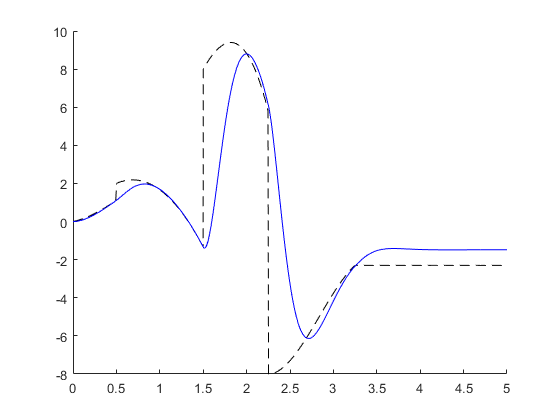

clear
HW10_2_script